group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';
rsa_obj2seq_group = load_mat([group_dir,'rsa_obj2seq_group.mat']);
rsa_same = rsa_obj2seq_group.same;
rsa_diff = rsa_obj2seq_group.diff;

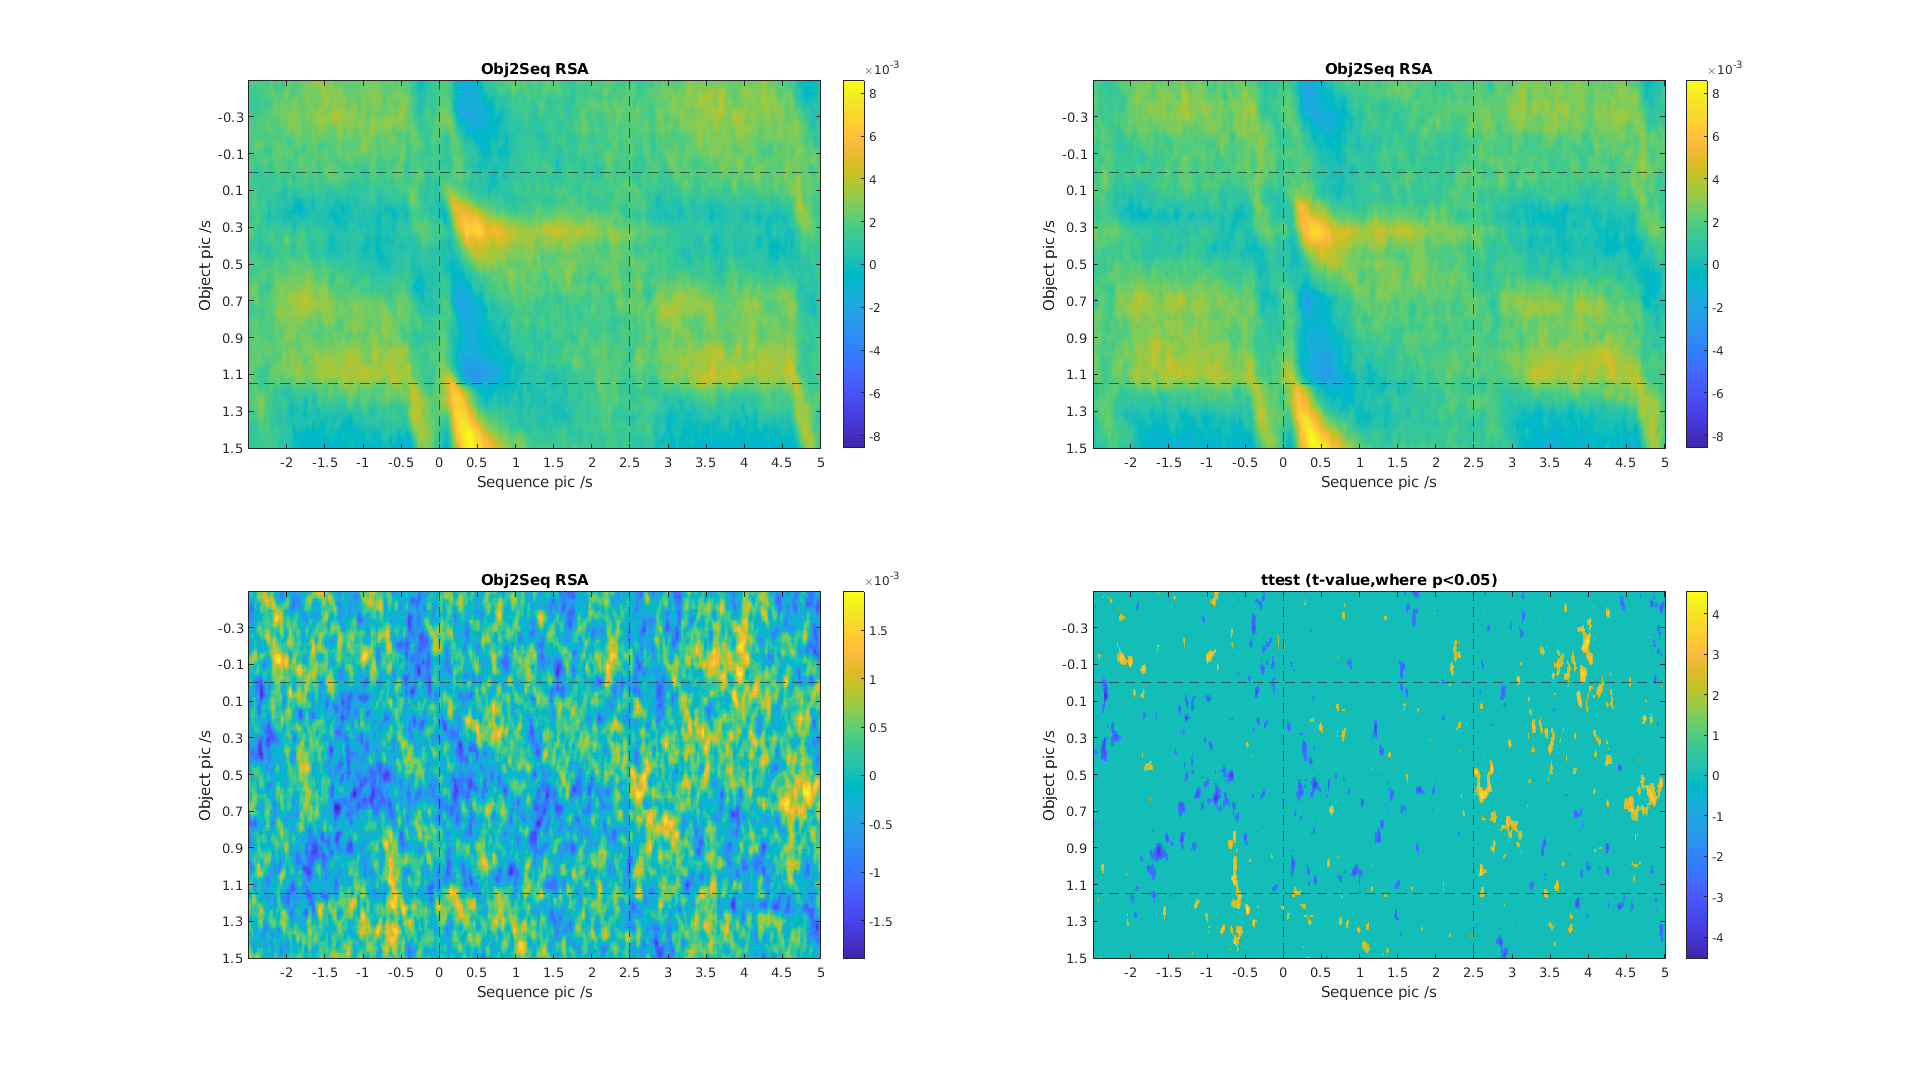

% obj2seq same diff
plt_rsa_sd(rsa_same,rsa_diff,'obj2seq');

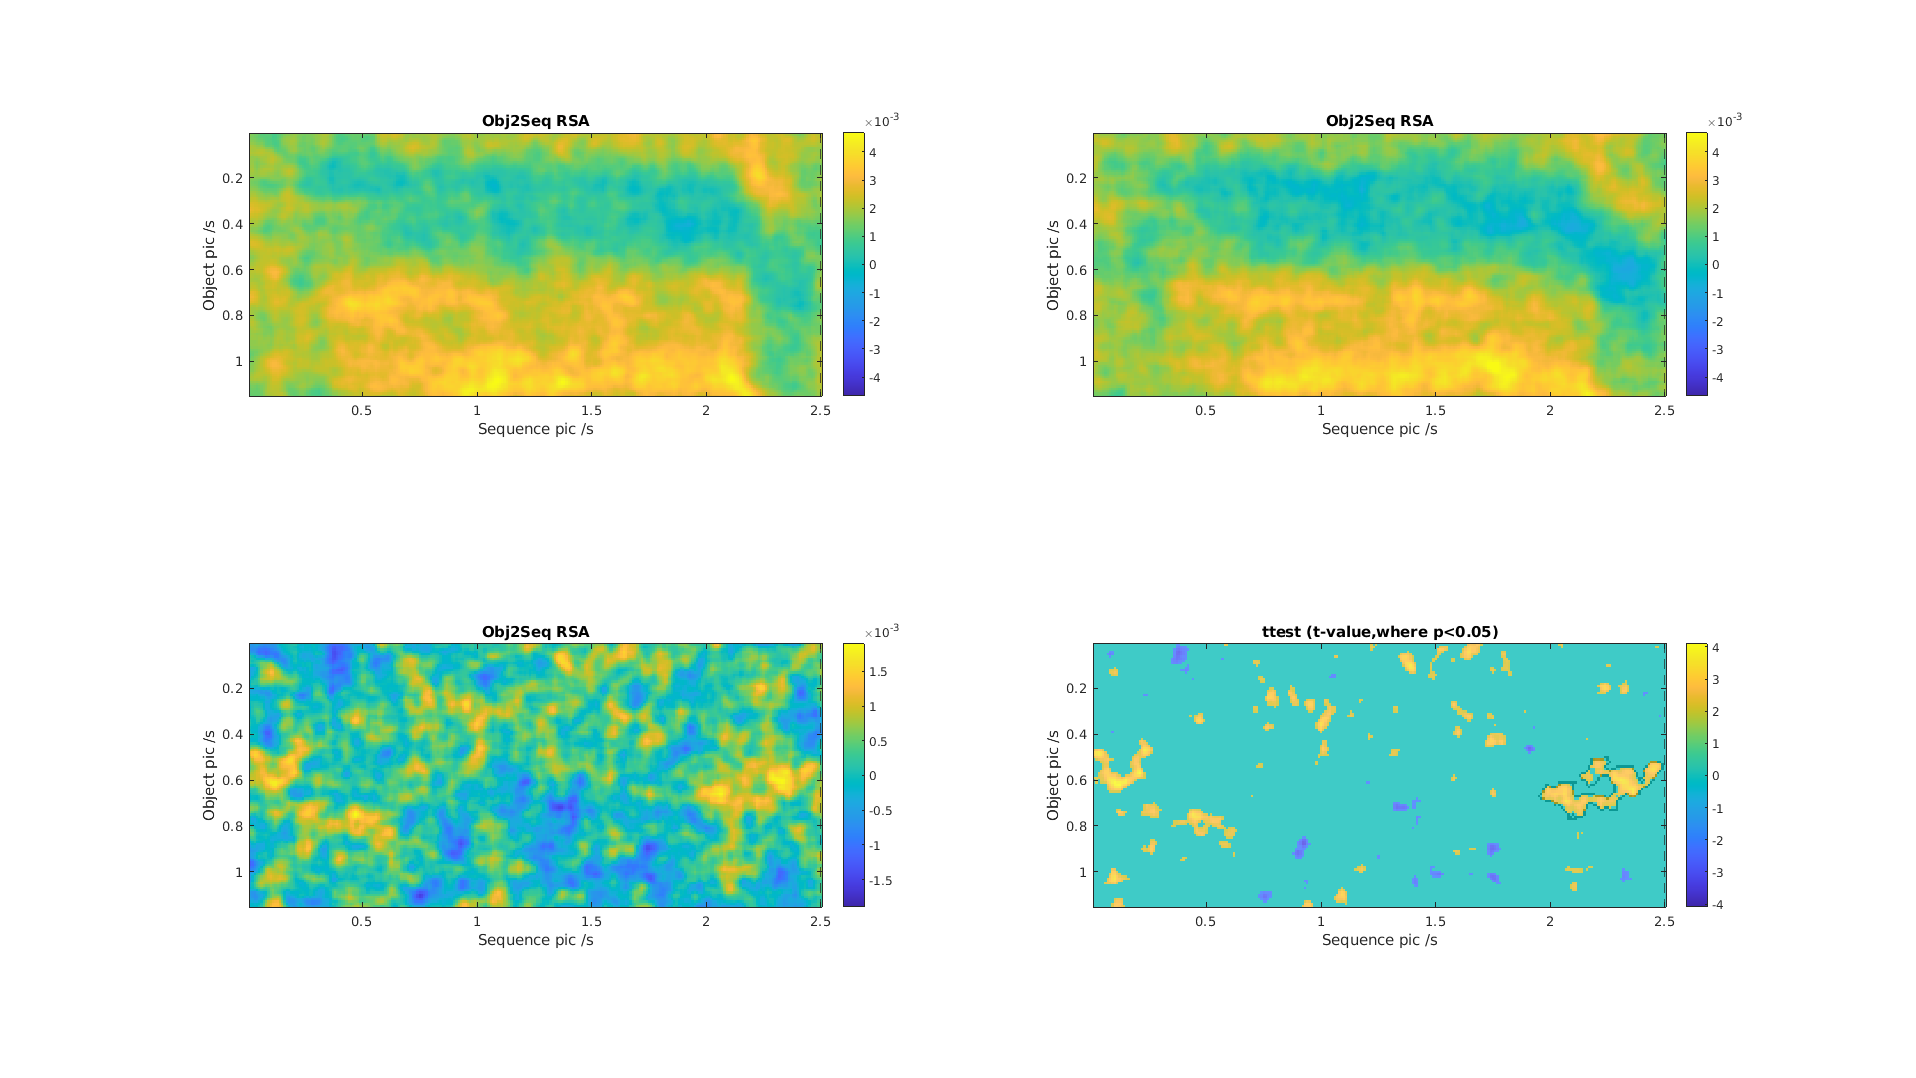

% permutation
[cp,pp,~,~] = plt_rsa_sd_perm(rsa_same(51:165,501:750,:),rsa_diff(51:165,501:750,:),'obj2seq_s');

pp

pp =     0.0393    0.1987    0.3761    0.8663    0.9290    0.9467    0.9548    0.9613    0.9691    0.9720    0.9758    0.9820    0.9830    0.9894    0.9917    0.9933    0.9947    0.9974    0.9984    0.9994    0.9996    0.9996    0.9996    0.9998    0.9998    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


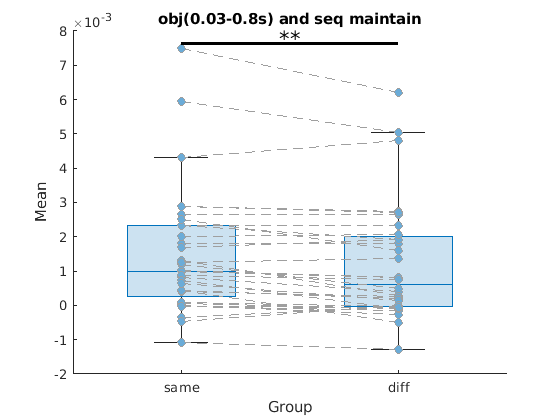

% caculate mean y[0.03-0.8s]  x[2.5-5s]
mean1(:,1) = squeeze(mean(rsa_same(53:130,501:750,:),[1,2]));
mean1(:,2) = squeeze(mean(rsa_diff(53:130,501:750,:),[1,2]));
figure
plt_box_line(mean1,{'same','diff'})
title('obj(0.03-0.8s) and seq maintain')

% load obj2seq_bd
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';
load_mat([group_dir,'rsa_obj2seq_bd.mat']);

% cell array to matrix
for i=1:18 % pics
    bd(:,:,:,i) = cell2matrix(rsa_group.bd(:,i));
    non_bd(:,:,:,i) = cell2matrix(rsa_group.non_bd(:,i));
end

Unrecognized field name "bd".

% color change vs no color change
data1 = mean(bd(51:120,351:450,:,:),4);
data2 = mean(non_bd(51:120,351:450,:,:),4);
[cp,pp,~,~] =plt_rsa_sd_perm(data1,data2,'obj2seq_s');

% plot mask
figure
mask = NaN(size(data1(:,:,1)));
mask(cp{1, 1}) = 1;
imagesc(mask)

% bd-non bd caculate mean y[0.15-0.75s]  x[2.5-5s]
for i=1:18 % pics
    data_bd = bd(:,:,:,i);
    data_non_bd = non_bd(:,:,:,i);
    for j =1:20 % sub_ids
        mean_bd(j,i) = mean(data_bd(51:120,351:450,j).*mask,[1,2],'omitnan');
        mean_non_bd(j,i) = mean(data_non_bd(51:120,351:450,j).*mask,[1,2],'omitnan');
    end
end
figure
plt_box_line([mean(mean_bd,2),mean(mean_non_bd,2)],{'color change','no color change'})

% position
temp=[];
temp(:,1)=mean(mean_bd(:,[7,13]),2);
temp(:,2)=mean(mean_bd(:,[1:6,8:12,14:18]),2);
figure
plt_box_line(temp,{'bd','non bd'})
title('bounday position')

% position 18
figure 
subplot(2,1,1)
bar(mean(mean_bd,1))
title('boundary')
subplot(2,1,2)
bar(mean(mean_non_bd,1))
title('no boundary')